## **AOMIC PIOP2 Replication Sample - Region-Specific Coupling All Conditions - 4 Measures **

Computation of region-specific SC-FC coupling maps (measure that is able to explain the highest variance in FC across all participants most frequently) and creation of correlation matrix depicting the similarity between vectors of regional SC-FC coupling pattern. 

Before running this script: 

- run all scripts in AOMIC Data Prep

**1. Create a group-average map depicting the regional SC-FC coupling pattern for each condition**

1. Create a cell that contains for each subject a vector of 4 predictors for each node 

for i = 1:180
    x = final_r_all_AOMIC_PIOP2_stop_signal_180{i,3};% change here to switch between the 4 conditions(rest/task) 
    for j = 1:358
    Node_all_baseline_best_measures_AOMIC_PIOP2_r2{i,j} = x(j,:);
    end
end


1.2. Create a cell containing information about all subjects and coupling measures per node

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 180*4 matrix for each node)

n = size(Node_all_baseline_best_measures_AOMIC_PIOP2_r2,2);
All_Nodes_complete_baseline_best_measures_AOMIC_PIOP2_r2 = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_AOMIC_PIOP2_r2{j} = vertcat(Node_all_baseline_best_measures_AOMIC_PIOP2_r2{:,j});
end 

1.3. Collect the highest coupling value and the respective coupling measure per node 

Max_values_individuals_AOMIC_PIOP2 = zeros(180,358);
Max_indices_individuals_AOMIC_PIOP2 = zeros(180,358);

for i = 1:358
    node_values = All_Nodes_complete_baseline_best_measures_AOMIC_PIOP2_r2{1,i};

    for p = 1:180
        individual_values = node_values(p,:);
        max_r2 = max(individual_values);
        idx_max = find(individual_values == max_r2); 
        
        if size(idx_max,2) == 2
            idx_max = idx_max(randi(length(idx_max),1)) %if two values have the exact same magnitude that this is randomly picking one out of the two 
        end
        
        Max_values_individuals_AOMIC_PIOP2(p,i) = max_r2;
        Max_indices_individuals_AOMIC_PIOP2(p,i) = idx_max;

    end
end

1.4. Find out mode for each node (group-based mask) 

Mode_for_all_nodes = zeros(1,358);

for i = 1:358
    all_selected_measures_per_node = Max_indices_individuals_AOMIC_PIOP2(:,i);
    [mode_node,frequency_mode] = mode(all_selected_measures_per_node);
    Mode_for_all_nodes(1,i) = mode_node;
end

1.5. Extract the values per node from measure that was selected with the highest frequency (mode) and average across all participants 

Mean_values_across_all_nodes = zeros(1,358);
Stdev_values_across_all_nodes = zeros(1,358);

for i = 1:358
    
node_values = All_Nodes_complete_baseline_best_measures_AOMIC_PIOP2_r2{1,i};
measure_highest_occurence = Mode_for_all_nodes(i);
node_values_measure_highest_occurence = node_values(:,measure_highest_occurence);

mean_per_node = mean(node_values_measure_highest_occurence);
stdev_per_node = std(node_values_measure_highest_occurence);

Mean_values_across_all_nodes(1,i) = mean_per_node;
Stdev_values_across_all_nodes(1,i) = stdev_per_node;

end

**2. Create the brain maps **

2.1. Convert Cell to mat

Mean_values_across_all_nodes_mat = Mean_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Mean_values_across_all_nodes_mat =     0.1781    0.1093    0.1732    0.2231    0.2361    0.2633    0.2726    0.1937    0.2010    0.0936    0.0718    0.1037    0.2496    0.1099    0.1035    0.2060    0.1775    0.1516    0.2354    0.2327    0.1960    0.1683    0.1247    0.0887    0.0582    0.0723    0.0965    0.0749    0.0677    0.1087    0.1013    0.0699    0.1189    0.1155    0.1440    0.0826    0.1004    0.1038    0.1031    0.1835    0.0931    0.1005    0.1081    0.0974    0.0947    0.0925    0.1213    0.0812    0.0748    0.1045


min(Mean_values_across_all_nodes_mat)

ans = 0.0288

max(Mean_values_across_all_nodes_mat)

ans = 0.2869

2.2. Insert a 0 at node 120 & 300

a = Mean_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Mean_values_across_all_nodes_mat_360 = a

Mean_values_across_all_nodes_mat_360 =     0.1781    0.1093    0.1732    0.2231    0.2361    0.2633    0.2726    0.1937    0.2010    0.0936    0.0718    0.1037    0.2496    0.1099    0.1035    0.2060    0.1775    0.1516    0.2354    0.2327    0.1960    0.1683    0.1247    0.0887    0.0582    0.0723    0.0965    0.0749    0.0677    0.1087    0.1013    0.0699    0.1189    0.1155    0.1440    0.0826    0.1004    0.1038    0.1031    0.1835    0.0931    0.1005    0.1081    0.0974    0.0947    0.0925    0.1213    0.0812    0.0748    0.1045


Mean_values_across_all_nodes_mat_360(120) = NaN;
Mean_values_across_all_nodes_mat_360(300)= NaN;

2.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Mean_values_across_all_nodes_mat_360

dataVec =     0.1781    0.1093    0.1732    0.2231    0.2361    0.2633    0.2726    0.1937    0.2010    0.0936    0.0718    0.1037    0.2496    0.1099    0.1035    0.2060    0.1775    0.1516    0.2354    0.2327    0.1960    0.1683    0.1247    0.0887    0.0582    0.0723    0.0965    0.0749    0.0677    0.1087    0.1013    0.0699    0.1189    0.1155    0.1440    0.0826    0.1004    0.1038    0.1031    0.1835    0.0931    0.1005    0.1081    0.0974    0.0947    0.0925    0.1213    0.0812    0.0748    0.1045


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.3500]
    viewcMap: 1
     viewStr: 'all'


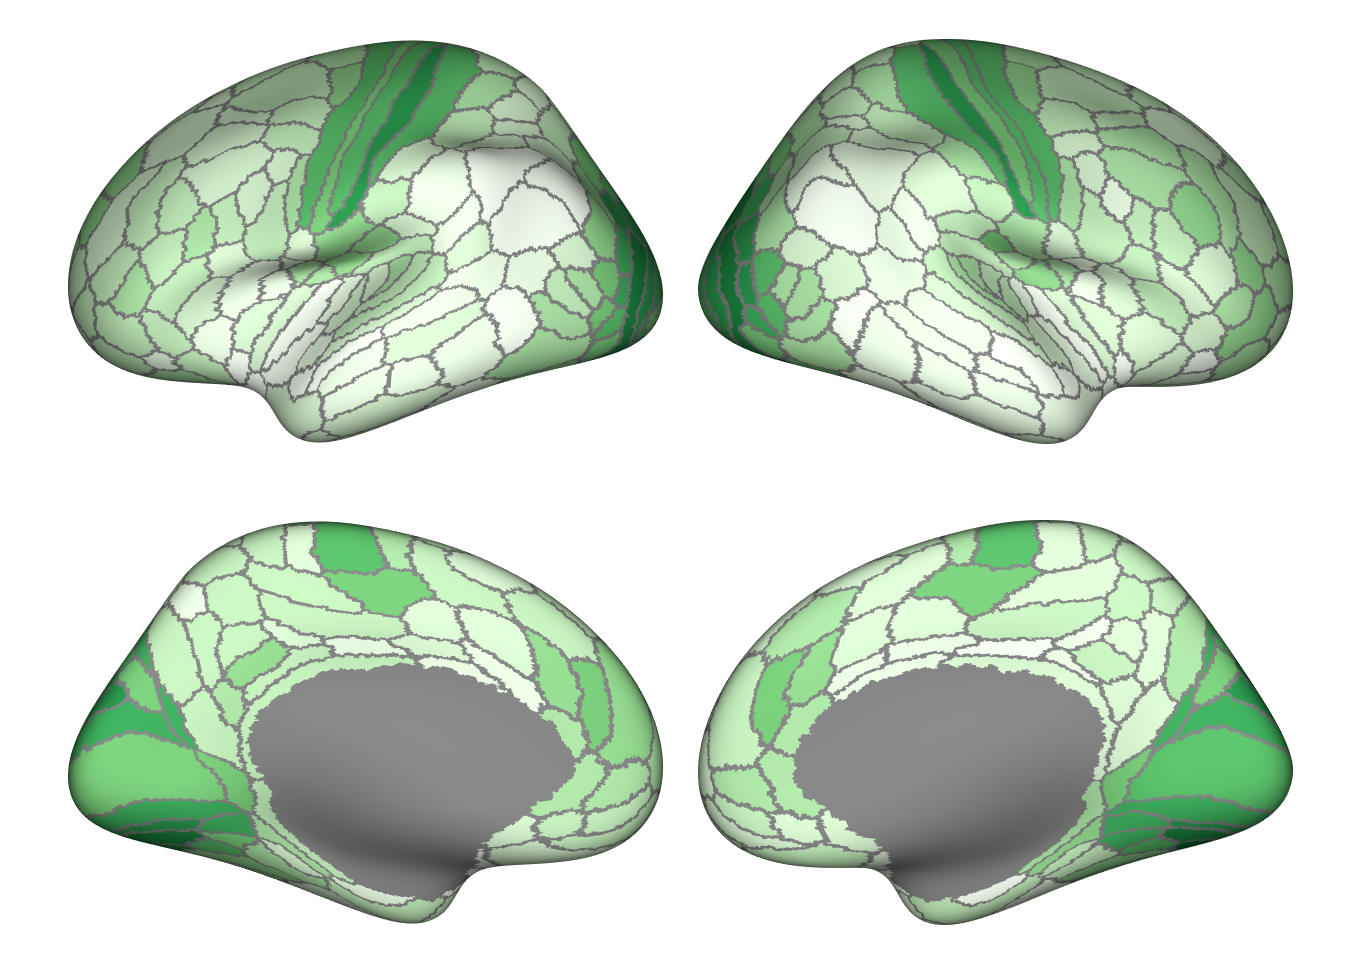

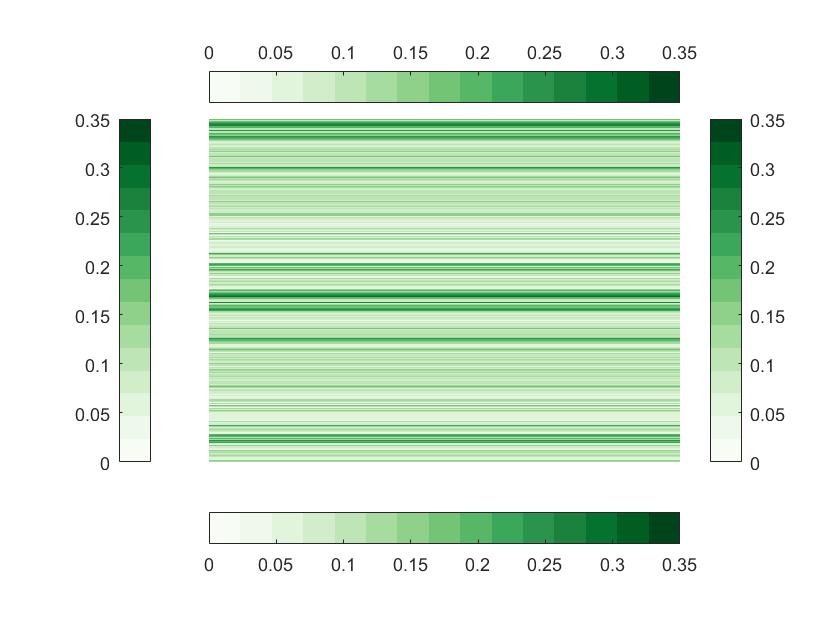

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Greens'),...
    'viewcMap',1, 'valRange', ([0 0.35]))

**3. Create the brain maps (Stdev)**

3.1. Convert cell to mat

Stdev_values_across_all_nodes_mat = Stdev_values_across_all_nodes % rename the variable here depending on condition that input data is coming from (important for the correlation matrix later)

Stdev_values_across_all_nodes_mat =     0.0785    0.0688    0.0800    0.0675    0.0712    0.0453    0.1020    0.0658    0.0753    0.0780    0.0764    0.0572    0.0931    0.0391    0.0786    0.1079    0.0874    0.0804    0.0988    0.1056    0.1116    0.1105    0.0710    0.0460    0.0302    0.0629    0.0418    0.0350    0.0659    0.0379    0.0467    0.0416    0.0383    0.0409    0.0433    0.0503    0.0413    0.0710    0.0496    0.0569    0.0742    0.0397    0.0447    0.0836    0.0561    0.0720    0.0546    0.0626    0.0514    0.0736


min(Stdev_values_across_all_nodes_mat)

ans = 0.0210

max(Stdev_values_across_all_nodes_mat)

ans = 0.1116

3.2. Insert a 0 at node 120 & 300

a = Stdev_values_across_all_nodes_mat;
b = 0;
idx_120 = 120;
idx_300 = 300;

a = [a(1:length(a)< idx_120),b,a(1:length(a) >= idx_120)];
a = [a(1:length(a)< idx_300),b,a(1:length(a) >= idx_300)];

Stdev_values_across_all_nodes_mat_360 = a

Stdev_values_across_all_nodes_mat_360 =     0.0785    0.0688    0.0800    0.0675    0.0712    0.0453    0.1020    0.0658    0.0753    0.0780    0.0764    0.0572    0.0931    0.0391    0.0786    0.1079    0.0874    0.0804    0.0988    0.1056    0.1116    0.1105    0.0710    0.0460    0.0302    0.0629    0.0418    0.0350    0.0659    0.0379    0.0467    0.0416    0.0383    0.0409    0.0433    0.0503    0.0413    0.0710    0.0496    0.0569    0.0742    0.0397    0.0447    0.0836    0.0561    0.0720    0.0546    0.0626    0.0514    0.0736


Stdev_values_across_all_nodes_mat_360(120) = NaN;
Stdev_values_across_all_nodes_mat_360(300)= NaN;

3.3. Plot

annotName = 'hcp-mmp-b'

annotName = 'hcp-mmp-b'

dataVec = Stdev_values_across_all_nodes_mat_360

dataVec =     0.0785    0.0688    0.0800    0.0675    0.0712    0.0453    0.1020    0.0658    0.0753    0.0780    0.0764    0.0572    0.0931    0.0391    0.0786    0.1079    0.0874    0.0804    0.0988    0.1056    0.1116    0.1105    0.0710    0.0460    0.0302    0.0629    0.0418    0.0350    0.0659    0.0379    0.0467    0.0416    0.0383    0.0409    0.0433    0.0503    0.0413    0.0710    0.0496    0.0569    0.0742    0.0397    0.0447    0.0836    0.0561    0.0720    0.0546    0.0626    0.0514    0.0736


ans = struct with fields:
      border: 1
        cMap: [15×3 double]
      newFig: 1
    valRange: [0 0.1000]
    viewcMap: 1
     viewStr: 'all'


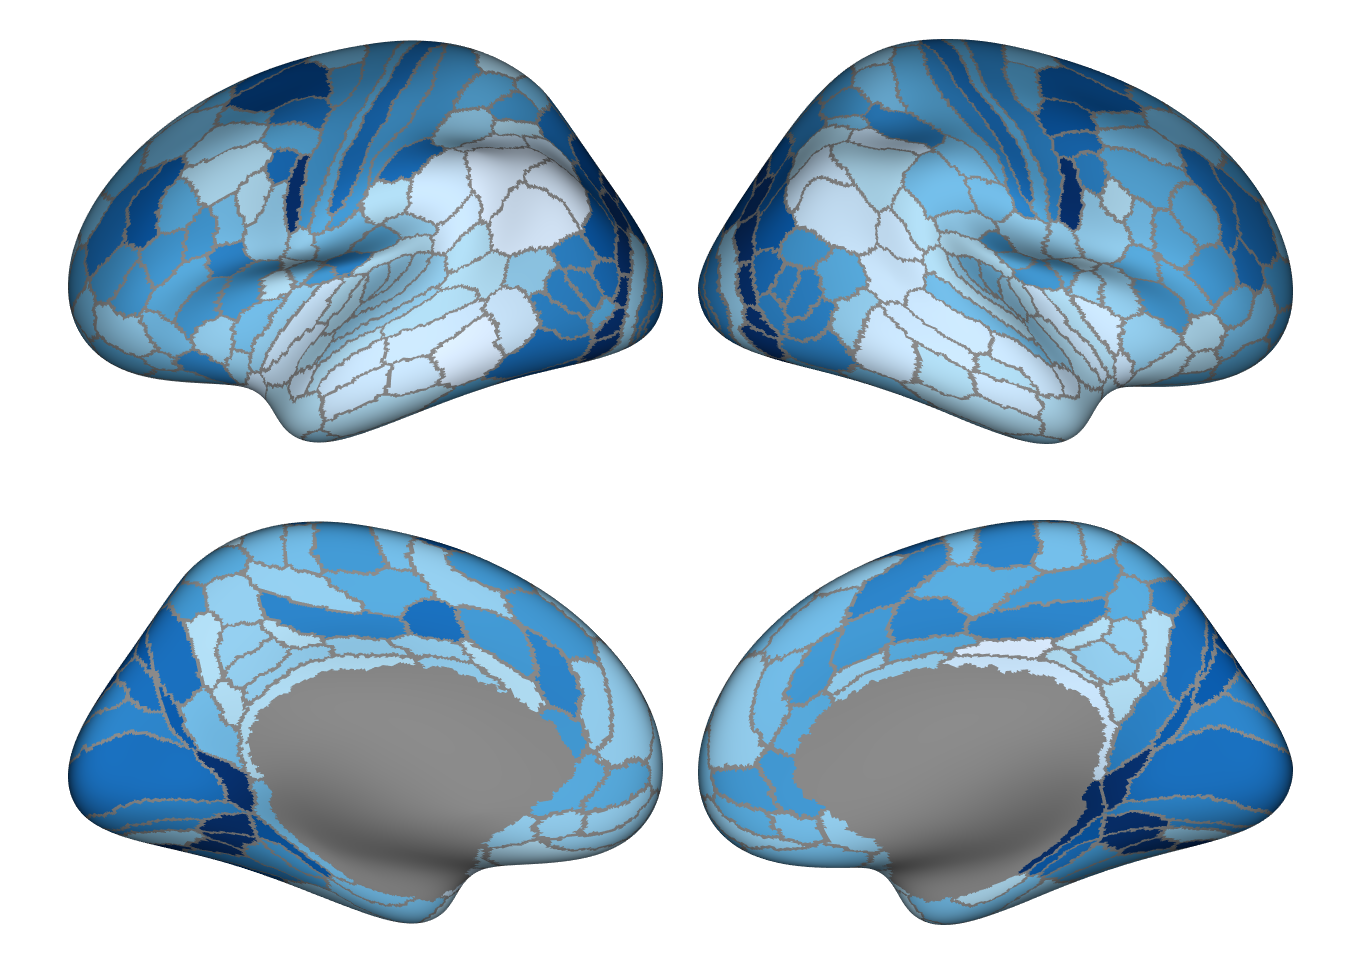

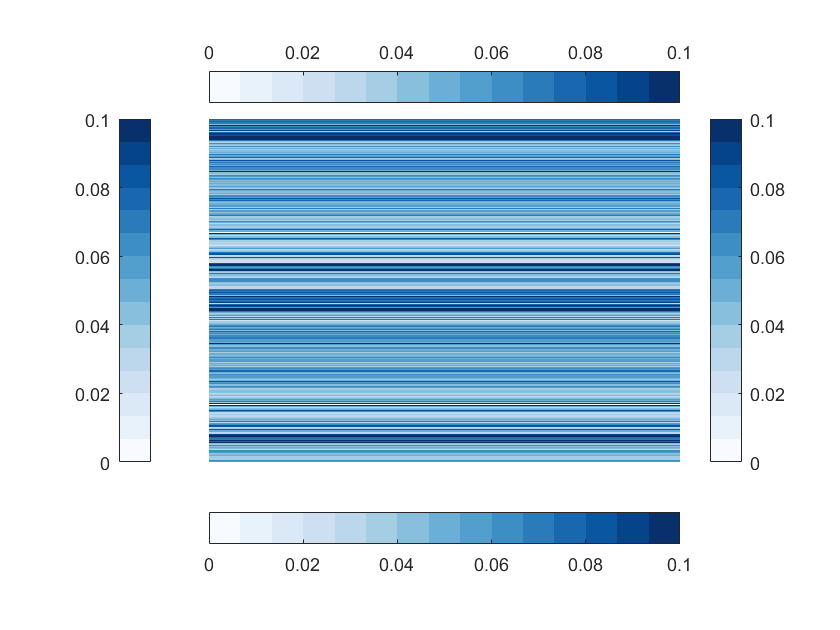

ans = 4×1 cell array
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}
    {1×1 Patch}


parc_plot(surfStruct,annotMap,annotName,dataVec,'cMap',brewermap(15,'Blues'),...
    'viewcMap',1, 'valRange', ([0 0.1]))

**4. Creation of correlation matrix depicting the similarity of condition-specific SC-FC coupling patterns**

4.1. Create the correlation matrix

coupling_vectors_all_conditions = [Mean_values_across_all_nodes_rest' Mean_values_across_all_nodes_wm' Mean_values_across_all_nodes_emo_match' Mean_values_across_all_nodes_stop_signal']

Unrecognized function or variable 'Mean_values_across_all_nodes_rest'.

correlation_matrix = corrcoef(coupling_vectors_all_conditions)

4.2. Plot the correlation matrix 

imagesc(correlation_matrix)
colorbar
set(gca, 'XTick', 1:4); % center x-axis ticks on bins
set(gca, 'YTick', 1:4); % center y-axis ticks on bins
xticklabels({'rest', 'wm', 'emo match' ,'stop signal'})
set(gca,'xaxisLocation','top')
yticklabels({'rest', 'wm', 'emo match' ,'stop signal'})
title('Correlation between condition-specific coupling measures', 'FontSize', 10); % set title
colormap('jet'); % Choose jet or any other color scheme
colorbar; 
caxis([.73 1]);